# Programming Language Exercises - Solutions

## Importing and Manipulating Data

Import the data from 2-subjects.csv as an array, matrix or equivalent

subjects = readmatrix("2-subjects.csv");
whos subjects % check dimensions

  Name            Size             Bytes  Class     Attributes

  subjects      164x82            107584  double              



Separate that data into 2 variables. 

subj1 = subjects(1:end/2, :);
subj2 = subjects((end/2+1:end),:);

Import the data from coords.csv

coords = readmatrix("coords.csv");

## Plotting Data

Heatmaps of connectivity (edge strength)

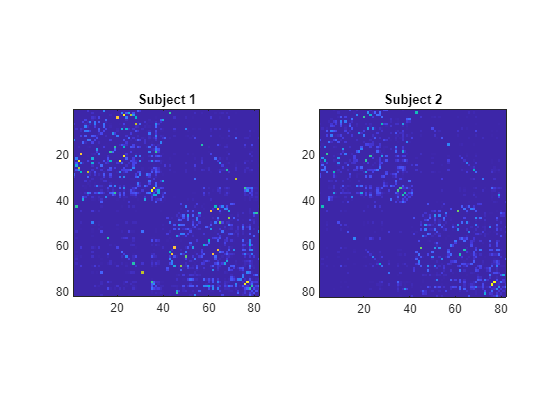

figure; 

subplot(1, 2, 1);
imagesc(subj1);
axis square; 
title('Subject 1');

subplot(1, 2, 2);
imagesc(subj2);
axis square; 
title('Subject 2');

Degree distributions

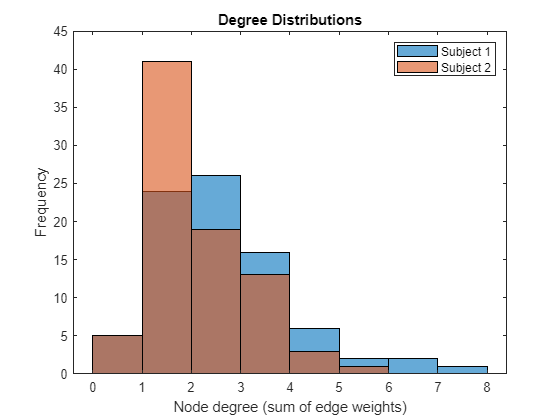

figure; 
histogram(sum(subj1));
hold on; 
histogram(sum(subj2));
title('Degree Distributions');
xlabel("Node degree (sum of edge weights)");
ylabel("Frequency");
legend("Subject 1", "Subject 2");

3-D plot

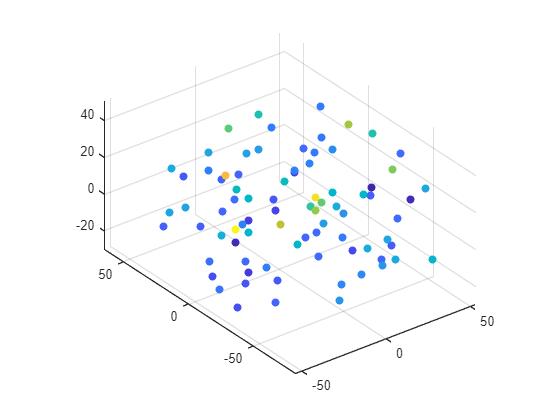

figure; 
scatter3(coords(:,1), coords(:,2), coords(:,3), [], mean([sum(subj1); sum(subj2)]), 'filled');
axis equal

## Analysing Data

Scatterplot of edge weights (logarithm)

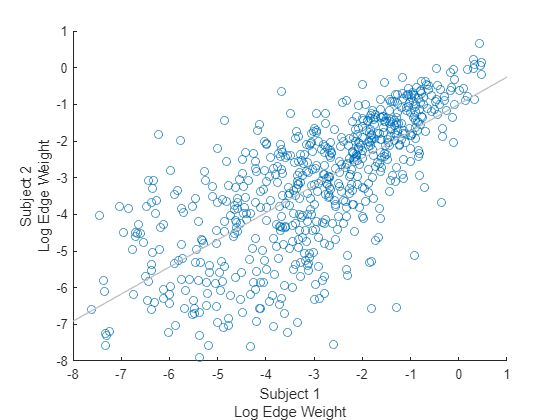

idx = subj1 & subj2; % find indices
data1 = log(subj1(idx));
data2 = log(subj2(idx));
figure; scatter(data1, data2); h = lsline;
xlabel({"Subject 1", "Log Edge Weight"});
ylabel({"Subject 2", "Log Edge Weight"});

fprintf('Correlation between log(subj1 edge weight) and log(subj2 edge weight) is %f\n', corr(data1, data2));

Correlation between log(subj1 edge weight) and log(subj2 edge weight) is 0.718259



% there are many ways to calculate the regression coefficients 
fprintf('Regression coefficients are\n')

Regression coefficients

p = [ones(size(data1)), data1]\data2

p =    -0.9963
    0.7398


p = regress(data2, [ones(size(data1)), data1])

p =    -0.9963
    0.7398


p = polyfit(get(h,'xdata'),get(h,'ydata'),1)

p =     0.7398   -0.9963


GLM of modes

modes = readmatrix("modes.csv");
subj1_degree = sum(subj1(1:34,:),2);

% get regression coefficients
beta = regress(subj1_degree, modes);
% reconstruct original using matrix multiplication
recon = modes*beta;
% an alternative: 
% recon = zeros(size(subj1_degree)); for ii = 1:length(beta); recon = recon + modes(:,ii)*beta(ii); end 
fprintf('Correlation between subj1 degree and 25 modes is %f\n', corr(recon, subj1_degree))

Correlation between subj1 degree and 25 modes is 0.904497



for ii = 5:5:25
    betaI = regress(subj1_degree, modes(:,1:ii));
    reconI = modes(:,1:ii)*betaI;
    fprintf('Using %i modes, recon accuracy = %f\n', ii, corr(reconI, subj1_degree));
end

Using 5 modes, recon accurracy = 0.668466
Using 10 modes, recon accurracy = 0.779506
Using 15 modes, recon accurracy = 0.827639
Using 20 modes, recon accurracy = 0.883510
Using 25 modes, recon accurracy = 0.904497


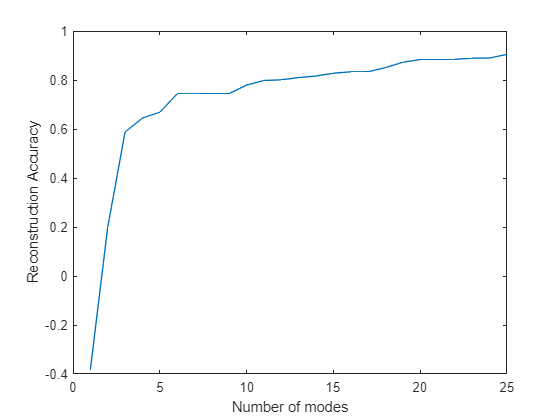


% create an anonymous function that does the calculations above
f = @(ii) corr(subj1_degree, modes(:,1:ii)*regress(subj1_degree, modes(:,1:ii)));
out = [];
for ii = 1:25
    out(ii) = f(ii); 
end
figure; plot(out);
xlabel("Number of modes");
ylabel("Reconstruction Accuracy");